# Using LBP Features to Differentiate Images by Texture

Team members:

- **Dacia Martínez Días A01733799**

- **Maxine Annnel Pacheco Ramírez A01551933**

- **Kristen Aideé Pérez Alvarez A00829551**

- **Allison Hernández Sánchez A01366543**

Read images that contain different textures.

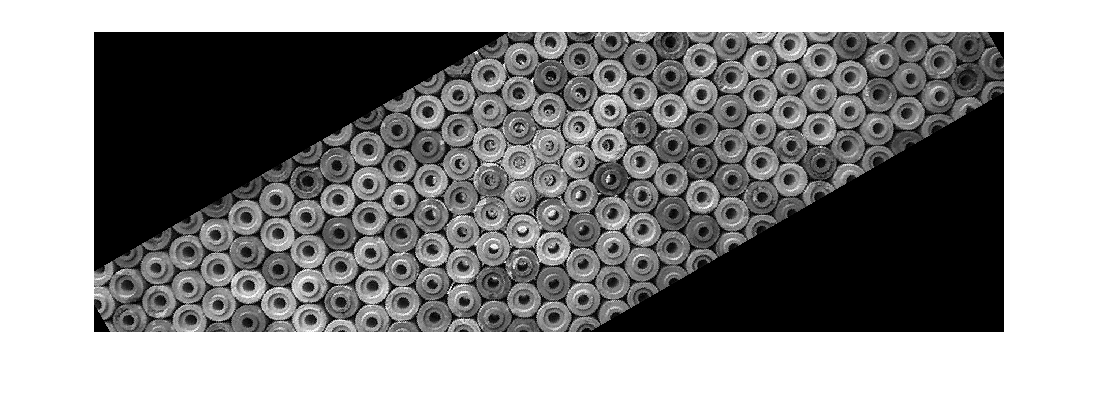

%brickWall = imread('bricks.jpg');
bri=imread('cieclewall.jpg');
brickWall = rgb2gray(bri);
% rotatedBrickWall = imread('bricksRotated.jpg');
J = imrotate( brickWall , 30, "crop" );
show= imshow(J);

pi= imread('piso.jpg');
piso = rgb2gray(pi);

Display the images.

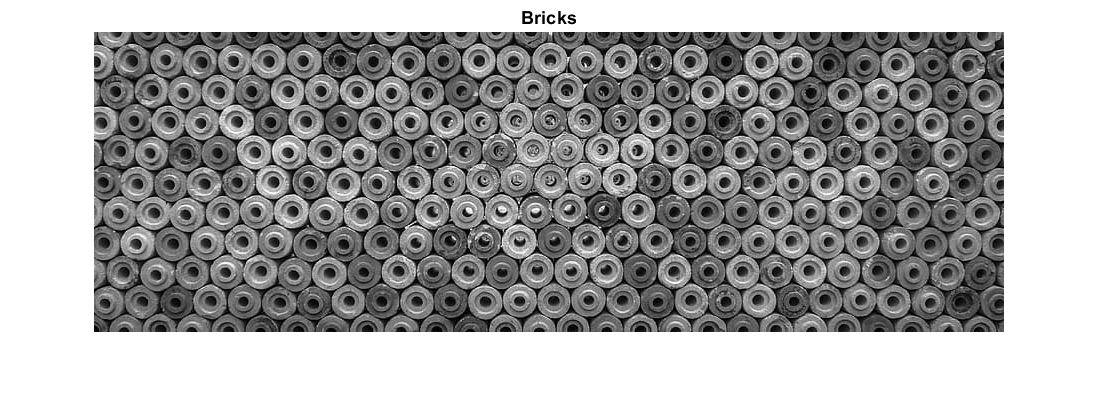

figure
imshow(brickWall)
title('Bricks')

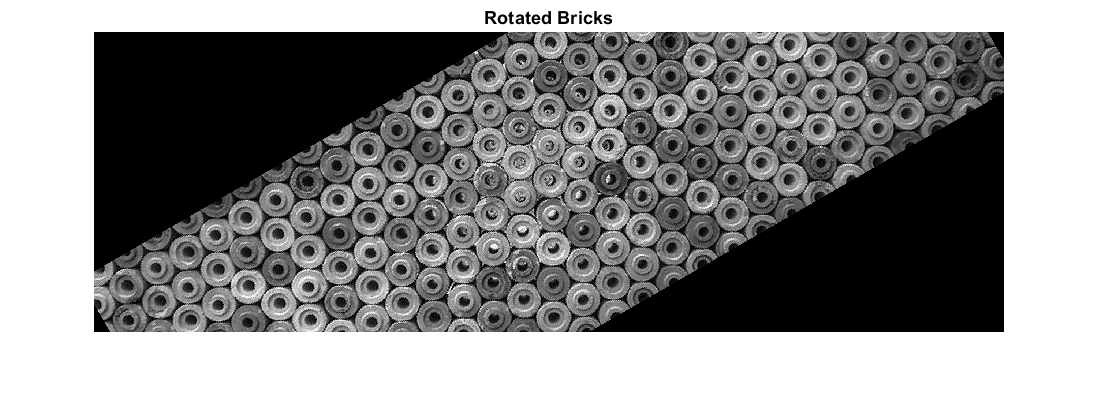

figure
imshow(J)
title('Rotated Bricks')

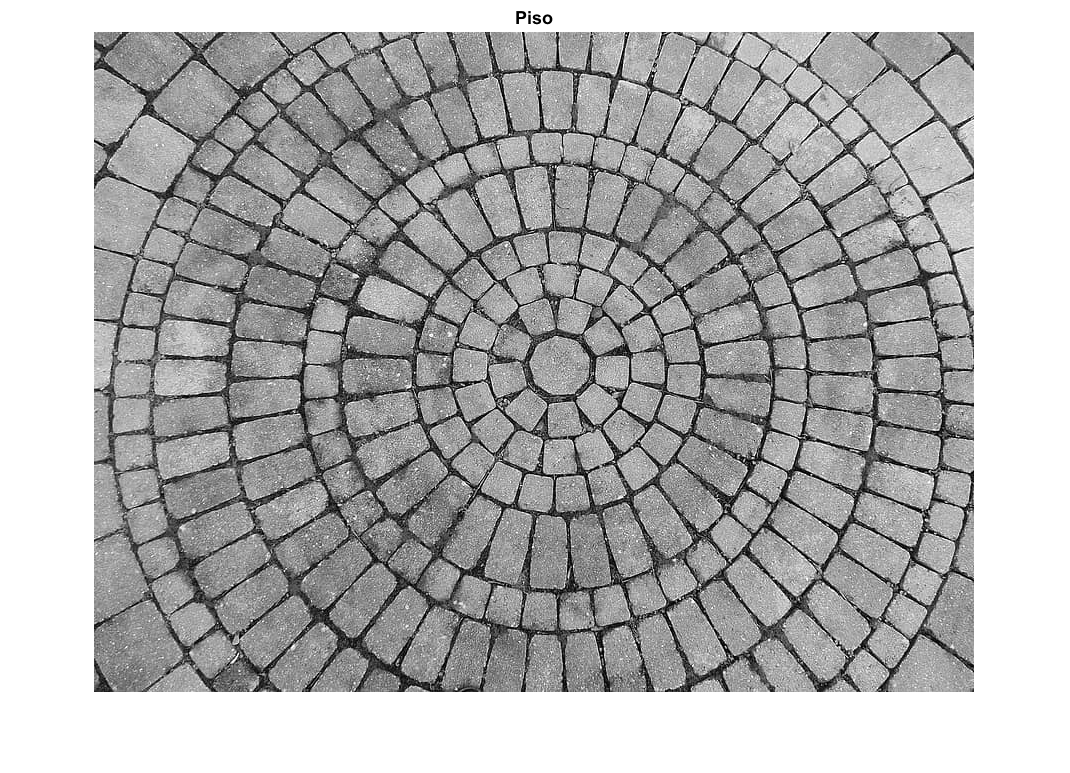

figure
imshow(piso)
title('Piso')

Extract LBP features from the images to encode their texture information.

lbpBricks1 = extractLBPFeatures(brickWall,'Upright',false);
lbpBricks2 = extractLBPFeatures(rotatedBrickWall,'Upright',false);
lbpCarpet = extractLBPFeatures(piso,'Upright',false);

Gauge the similarity between the LBP features by computing the squared error between them.

brickVsBrick = (lbpBricks1 - lbpBricks2).^2;
brickVsCarpet = (lbpBricks1 - lbpCarpet).^2;

Visualize the squared error to compare bricks versus bricks and bricks versus carpet. The squared error is smaller when images have similar texture.

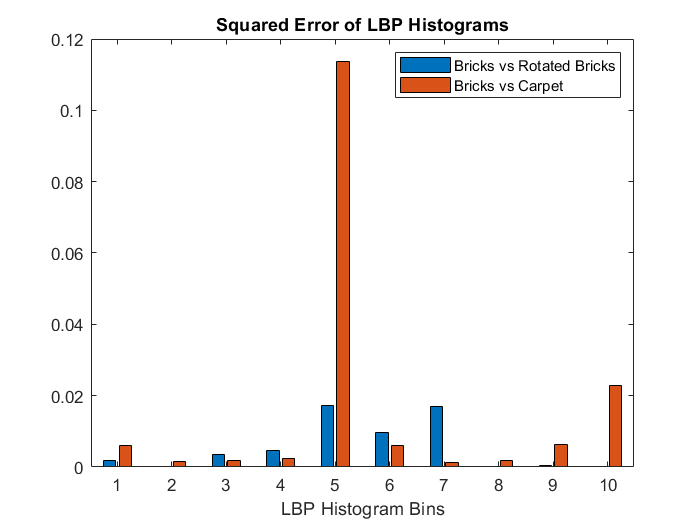

figure
bar([brickVsBrick; brickVsCarpet]','grouped')
title('Squared Error of LBP Histograms')
xlabel('LBP Histogram Bins')
legend('Bricks vs Rotated Bricks','Bricks vs Carpet')

# Apply L1 Normalization to LBP Features

Read in a sample image and convert it to grayscale.

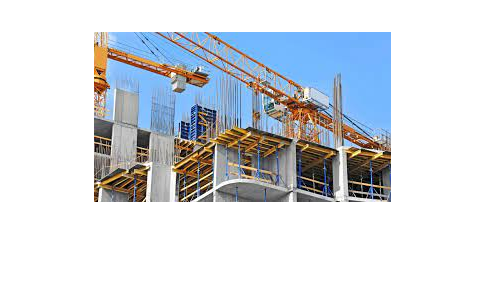

I = imread('construccion.jpg');
figure
imshow(I)

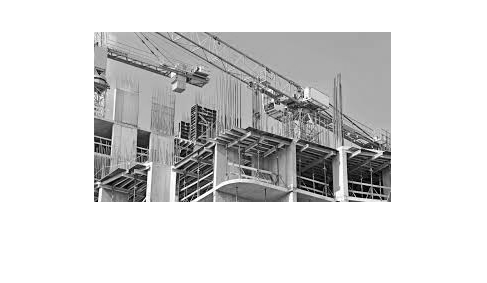

I = im2gray(I);
figure
imshow(I)

Extract unnormalized LBP features so that you can apply a custom normalization. 

lbpFeatures = extractLBPFeatures(I,'CellSize',[32 32],'Normalization','None');

Reshape the LBP features into a *number of neighbors* -by- *number of cells* array to access histograms for each individual cell.

numNeighbors = 8;
numBins = numNeighbors*(numNeighbors-1)+3;
lbpCellHists = reshape(lbpFeatures,numBins,[]);

Normalize each LBP cell histogram using L1 norm.

lbpCellHists = bsxfun(@rdivide,lbpCellHists,sum(lbpCellHists));

Reshape the LBP features vector back to 1-by- *N* feature vector.

lbpFeatures = reshape(lbpCellHists,1,[]);

*Copyright 2015 The MathWorks, Inc.*